**Context:** Prior exploration hints at the possiblity at formulating a method of quickly determining whether a given arm design can reach a target shape by only inspecting the reaction wrenches created at a select few pressure options that form the "edges" or even "vertices" of the control space.

**Goal:** In this document we will investigate

% Define arm base curve
% First we define the arm's design
rho_outer = 0.08;
rho_inner = 0.015;

rhos = [-rho_outer, -rho_inner, rho_inner, rho_outer];
mat_A = [
1, 1, 1, 1;
0, 0, 0, 0;
-rhos;
];

f_bellow = @JacobBellowMechanics.actuator_force;
f_muscle = @GinaMuscleMechanics.actuatorForce_key;
fs = {f_bellow, f_muscle, f_muscle, f_bellow};

l_0 = 0.5;

g_0 = Pose2.hat([0, 0, -pi/2]);
N_poses = 10;

% Combine the design parameters into a struct
struct_design = struct();
struct_design.mat_A = mat_A;
struct_design.l_0 = l_0;
struct_design.fs = fs;
struct_design.g_0 = g_0;
struct_design.rhos = rhos;

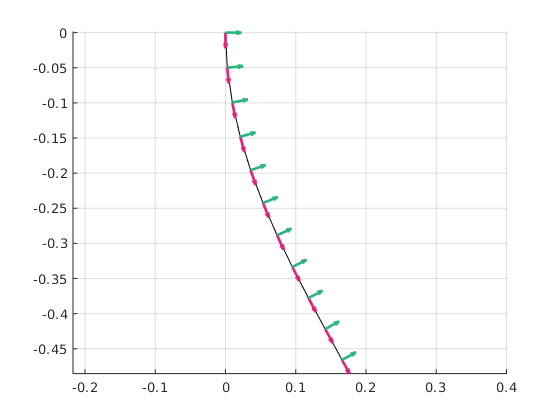

% Define the shape that the arm is held at
a = -1;
b = 1;

l = 0.5;
f_affine_curvature = @(s) [
    l*ones(size(s));
    zeros(size(s));
    a*s + b
];
s = linspace(0, 1, N_poses);
poses = f_calc_poses(g_0, f_affine_curvature, N_poses);
segment_twists = f_affine_curvature(s);

ax = axes(figure());
plot_poses(poses, ax);
grid on
set(gcf, "visible", true)

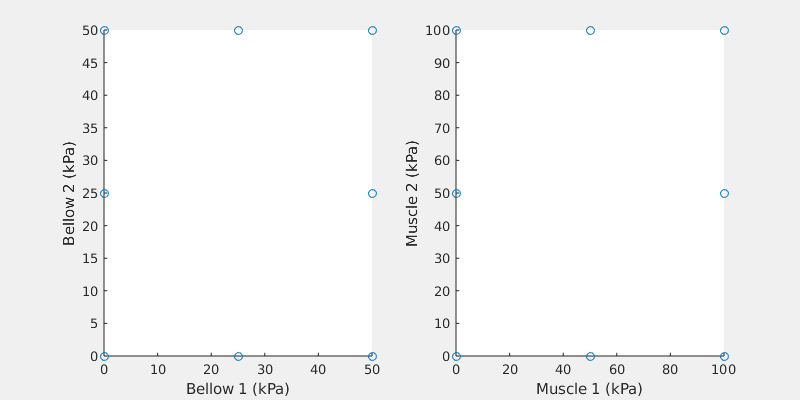

% Clearly our prism is not the full reaction image. But what is the full
% reaction image?
% This begs the question: what is the actual full reaction image?
%
% We can do this in two ways: we can compute the reactions for pressures
% along the edges of the hypercube. OR, we can do a monte-carlo sampling of
% random points in the pressure space

% METHOD 1: Sample a bunch of points in R4 bounded by [0; 0; 0; 0] and [50; 100; 100; 50]
rng(100);
p_max = [50, 100, 100, 50];
N_ps = 100;
ps_monte = diag(p_max) * betarnd(0.3, 0.3, 4, N_ps); % By using a beta distribution we can bias towards the edges

% METHOD 2: Use the vertices of the pressure space
bitstrings = (dec2bin(0:15) - '0')';
ps_monte = diag(p_max) * bitstrings;
N_ps = size(ps_monte, 2);

% % METHOD 3: Use the faces of the pressure space
% N_ps = 30;
% ps_monte = sample_faces_of_cuboid(N_ps, [50, 100, 100, 50]);
% % And append the vertices
% ps_monte = [ps_monte, diag(p_max) * bitstrings];
% N_ps = size(ps_monte, 2);

% METHOD 4: Use the edges of the pressure space
N_ps_per_edge = 2;
ps_monte = sample_edges_of_cuboid(N_ps_per_edge, [50, 100, 100, 50]);
N_ps = size(ps_monte, 2);

figure("Position", [0, 0, 800, 400])
subplot(1, 2, 1)
scatter(ps_monte(1, :), ps_monte(4, :));
xlabel("Bellow 1 (kPa)")
ylabel("Bellow 2 (kPa)")

subplot(1, 2, 2)
scatter(ps_monte(2, :), ps_monte(3, :));
xlabel("Muscle 1 (kPa)")
ylabel("Muscle 2 (kPa)")
set(gcf, "Visible", true)

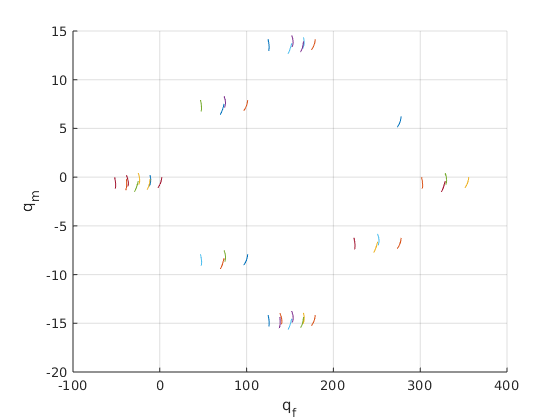

mat_s_monte = repmat(s, [N_ps, 1]);

[paths_qf_monte, paths_qm_monte] = compute_reaction_paths(ps_monte, segment_twists, struct_design);

figure()
hold on
plot3(paths_qf_monte, paths_qm_monte, mat_s_monte);
xlabel("q_f")
ylabel("q_m")
grid on
set(gcf, "Visible", true)

One thing that is noteworthy: we can immediately tell from this graph that not all pressures have equal change in reactions along the arm (the "hairs" don't all move in the same direction). Thus there is not an easy and universal way to check if the "direction" of the hair alignts with what is possible.

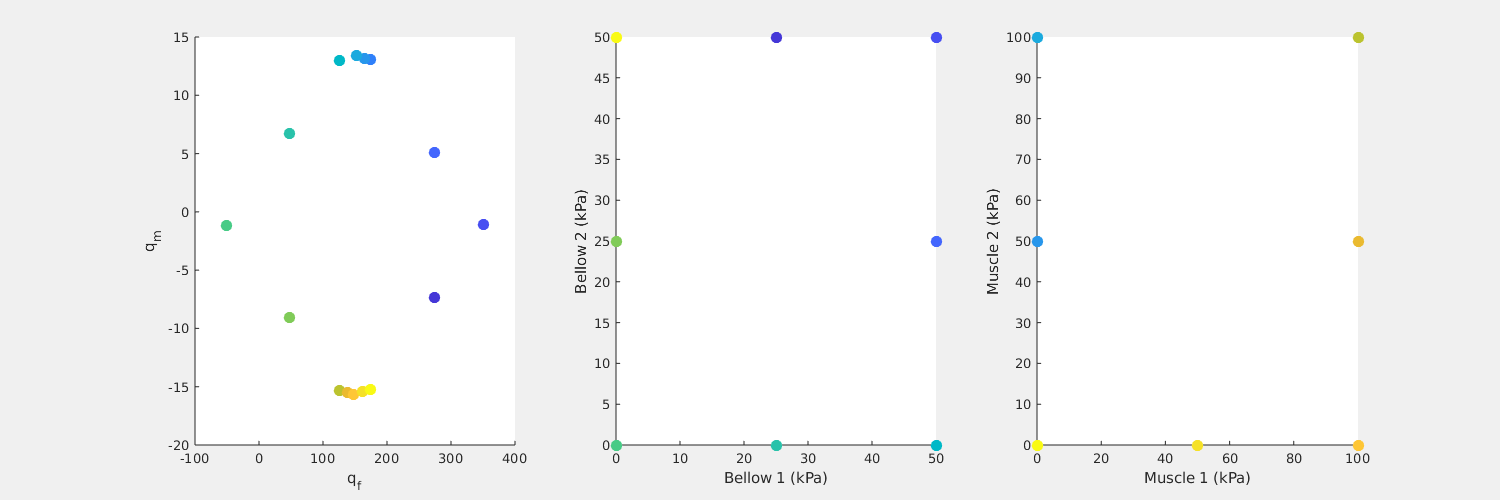

% Find the points that are on the outline of the base level, and then find
% their corresponding pressures. This will tell us which pressures to focus
% on.
i_bnd_qs = boundary(paths_qf_monte(1, :)', paths_qm_monte(1, :)', 0.1);
c = linspace(1, 10, length(i_bnd_qs));

figure("Position", [0, 0, 1500, 500])
subplot(1, 3, 1);
scatter(paths_qf_monte(1, i_bnd_qs), paths_qm_monte(1, i_bnd_qs), 75, c, "filled");
xlabel("q_f")
ylabel("q_m")

subplot(1, 3, 2)
scatter(ps_monte(1, i_bnd_qs), ps_monte(4, i_bnd_qs), 75, c, "filled");
xlabel("Bellow 1 (kPa)")
ylabel("Bellow 2 (kPa)")

subplot(1, 3, 3)
scatter(ps_monte(2, i_bnd_qs), ps_monte(3, i_bnd_qs), 75, c, "filled");
xlabel("Muscle 1 (kPa)")
ylabel("Muscle 2 (kPa)")
set(gcf, "Visible", true)

### **Test 1**

**Question:** For the given arm design, shape, and load, the pressures whose reactions bound all reactions at s=0 still bound the reactions for any other 0 < s < 1?

**Hypothesis:** Yes. This would imply that for he given arm design, shape, and load, a naively constructed reaction prism is a valid method of determining shape attainability.

% Create the test dataset
N_test_ps = 1000;
p_max = [50, 100, 100, 50];
ps_test = diag(p_max) * unifrnd(0, 1, 4, N_test_ps); % By using a beta distribution we can bias towards the edges

[paths_qf_test, paths_qm_test] = compute_reaction_paths(ps_test, segment_twists, struct_design);

is_bounded = false(N_poses, N_test_ps);
for i_s = 1 : N_poses
    % Check that the pressures that bounded the reactions at s=0 still
    % bound at 0 < s < 1
    query_qf = paths_qf_test(i_s, :);
    query_qm = paths_qm_test(i_s, :);
    
    boundary_qf = paths_qf_monte(i_s, i_bnd_qs);
    boundary_qm = paths_qm_monte(i_s, i_bnd_qs);

    is_bounded(i_s, :) = inpolygon(query_qf, query_qm, boundary_qf, boundary_qm);
end

all_bounded = all(is_bounded);
fprintf("Number of pressures whose reactions are fully bounded within: %d / %d = %.2f%%", nnz(all_bounded), N_test_ps, 100*nnz(all_bounded)/N_test_ps);

Number of pressures whose reactions are fully bounded within: 1000 / 1000 = 100.00%

% What are the outlier pressures?
ps_test(:, ~all_bounded)


ans =

  4×0 empty double matrix



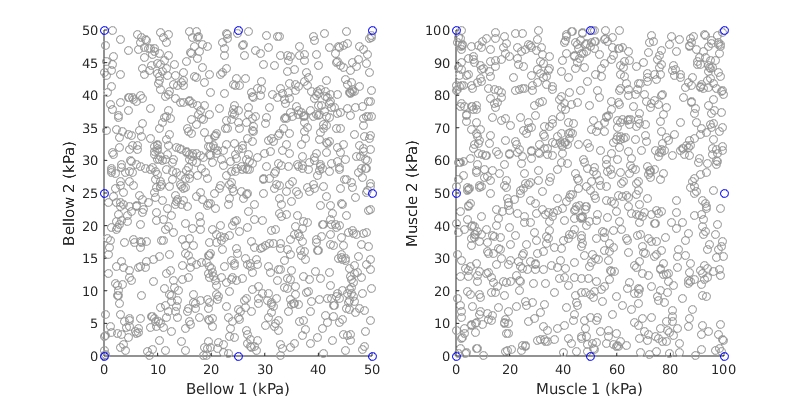

gray = [150,150,150]/255;
% Plot the outlier reactions and/or pressures
figure("Position", [0, 0, 800, 400])
subplot(1, 2, 1)
hold on
scatter(ps_test(1, :), ps_test(4, :), [], gray);
scatter(ps_monte(1, :), ps_monte(4, :), [], 'b');
scatter(ps_test(1, ~all_bounded), ps_test(4, ~all_bounded), 'filled');
xlabel("Bellow 1 (kPa)")
ylabel("Bellow 2 (kPa)")

subplot(1, 2, 2)
hold on
scatter(ps_test(2, :), ps_test(3, :),[], gray);
scatter(ps_monte(2, :), ps_monte(3, :), [], 'b');
scatter(ps_test(2, ~all_bounded), ps_test(3, ~all_bounded), 'filled');
xlabel("Muscle 1 (kPa)")
ylabel("Muscle 2 (kPa)")
set(gcf, "Visible", true)

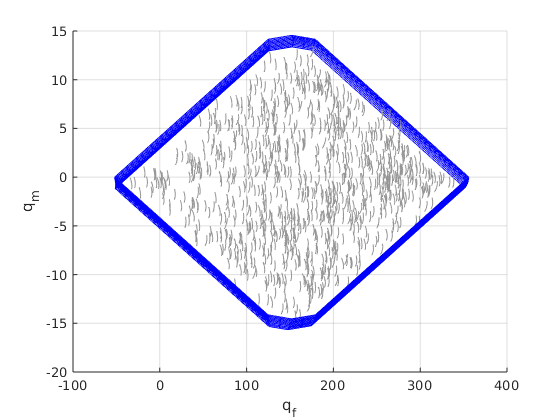

figure()
hold on
mat_s = repmat(s, [length(i_bnd_qs), 1]);
mat_s_test = repmat(s, [N_test_ps, 1]);
plot3(paths_qf_monte(:, i_bnd_qs)', paths_qm_monte(:, i_bnd_qs)', s, 'b');
plot3(paths_qf_monte(:, i_bnd_qs)', paths_qm_monte(:, i_bnd_qs)', mat_s, 'b');
plot3(paths_qf_test, paths_qm_test, mat_s_test, "color", gray);
plot3(paths_qf_test(:, ~all_bounded), paths_qm_test(:, ~all_bounded), mat_s_test(~all_bounded, :), 'r')
xlabel("q_f")
ylabel("q_m")
zlabel("s")
grid on
set(gcf, "Visible", true)

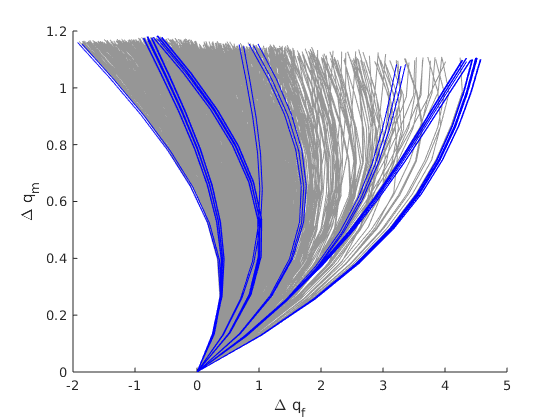

% Compare the "directions" of all of the hairs
displacements_qf_test = paths_qf_test - paths_qf_test(1, :);
displacements_qm_test = paths_qm_test - paths_qm_test(1, :);

displacements_qf_boundary = paths_qf_monte - paths_qf_monte(1, :);
displacements_qm_boundary = paths_qm_monte - paths_qm_monte(1, :);

figure()
hold on
plot(displacements_qf_test, displacements_qm_test, color=gray);
plot(displacements_qf_boundary, displacements_qm_boundary, color='b');
xlabel("\Delta q_f")
ylabel("\Delta q_m")
set(gcf, "Visible", true)

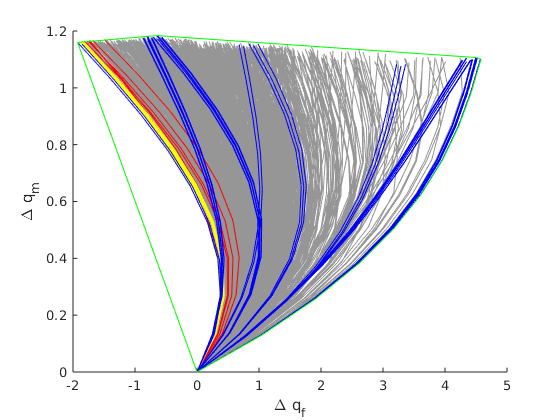

% Question: Which pressures correspond to reaction traces not bounded by
% the ones from the pressure boundary?
i_bounds_displacements_boundary = boundary(displacements_qf_boundary(:), displacements_qm_boundary(:), 0);
bound_disps_qf_boundary = displacements_qf_boundary(i_bounds_displacements_boundary);
bound_disps_qm_boundary = displacements_qm_boundary(i_bounds_displacements_boundary);

% Find traces where any point is outside of the convex hull of the blue
disps_in_bounds = inpolygon(displacements_qf_test, displacements_qm_test, bound_disps_qf_boundary, bound_disps_qm_boundary);
mask_disps_out = ~all(disps_in_bounds, 1);

% Get the left-most 10 displacements and find what pressures created them
[~, i_sort] = sort(displacements_qf_test(end, :));
i_left_most = i_sort(1:10);

figure()
hold on
plot(displacements_qf_test, displacements_qm_test, color=gray);
plot(displacements_qf_test(:, mask_disps_out), displacements_qm_test(:, mask_disps_out), 'r');
plot(displacements_qf_test(:, i_left_most), displacements_qm_test(:, i_left_most), 'y');
plot(displacements_qf_boundary, displacements_qm_boundary, color='b');
plot(bound_disps_qf_boundary, bound_disps_qm_boundary, 'g')
xlabel("\Delta q_f")
ylabel("\Delta q_m")
set(gcf, "Visible", true)

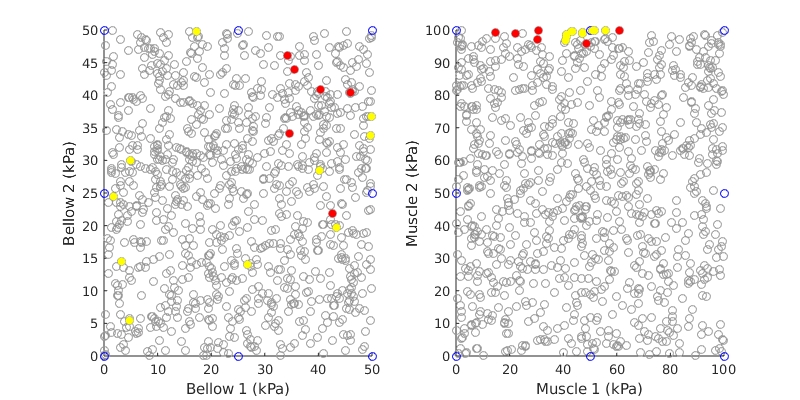


figure("Position", [0, 0, 800, 400])
subplot(1, 2, 1)
hold on
scatter(ps_test(1, :), ps_test(4, :), [], gray);
scatter(ps_monte(1, :), ps_monte(4, :), [], 'b');
scatter(ps_test(1, ~all_bounded), ps_test(4, ~all_bounded), 'filled');
scatter(ps_test(1, mask_disps_out), ps_test(4, mask_disps_out), 'r', 'filled')
scatter(ps_test(1, i_left_most), ps_test(4, i_left_most), 'y', 'filled')
xlabel("Bellow 1 (kPa)")
ylabel("Bellow 2 (kPa)")

subplot(1, 2, 2)
hold on
scatter(ps_test(2, :), ps_test(3, :),[], gray);
scatter(ps_monte(2, :), ps_monte(3, :), [], 'b');
scatter(ps_test(2, ~all_bounded), ps_test(3, ~all_bounded), 'filled');
scatter(ps_test(2, mask_disps_out), ps_test(3, mask_disps_out), 'r', 'filled')
scatter(ps_test(2, i_left_most), ps_test(3, i_left_most), 'y', 'filled')
xlabel("Muscle 1 (kPa)")
ylabel("Muscle 2 (kPa)")
set(gcf, "Visible", true)

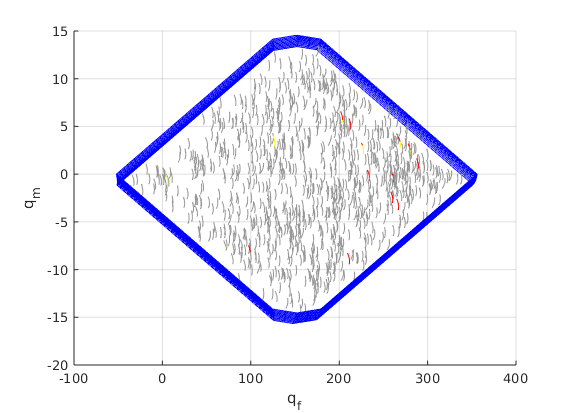

figure()
hold on
mat_s = repmat(s, [length(i_bnd_qs), 1]);
mat_s_test = repmat(s, [N_test_ps, 1]);
plot3(paths_qf_monte(:, i_bnd_qs)', paths_qm_monte(:, i_bnd_qs)', s, 'b');
plot3(paths_qf_monte(:, i_bnd_qs)', paths_qm_monte(:, i_bnd_qs)', mat_s, 'b');
plot3(paths_qf_test, paths_qm_test, mat_s_test, "color", gray);
plot3(paths_qf_test(:, mask_disps_out), paths_qm_test(:, mask_disps_out), mat_s_test(mask_disps_out, :), 'r')
plot3(paths_qf_test(:, i_left_most), paths_qm_test(:, i_left_most), mat_s_test(i_left_most, :), 'y')
xlabel("q_f")
ylabel("q_m")
zlabel("s")
grid on
set(gcf, "Visible", true)

### Test 2

Our goal is to use a small number K of pressures to determine a heuristic that can classify whether a given set of reactions along the arm $q_{\textrm{rec}}$ is within the image of the input pressure space under the internal reaction function: $q_{\textrm{rec}} \stackrel{?}{\in} a(P)$. In other words, we want to know if there exists $p \in P$ such that $q_{\textrm{rec}} = a(p)$ for some p.

So far we have investigated various methods for creating such a heuristic by examining conditions that are shared for all points in $a(P)$, such as the fact that they are all bounded by the $a(\partial P)$, and that the displacements $a(P) - a_0(P) \in \Delta a(\partial P)$ where $\Delta a(\partial P) = \{a(p) - a_0(p) \mid p \in \partial P\}$.

However, we have not yet been able to genuinely test the validity of such a heuristic. The converse is not the contrapositive: "$q \in a(P)$ then $q \in a(\partial P)$ and $q-q_0 \in \Delta a(\partial P)$" being true does not make its converse "If $q-q_0 \in \Delta a(\partial P)$ and $q \in a(\partial P)$ then $q \in a(P)$" true. It is conceivable that there exists $q \in \mathbb{R}^{20}$ such that both conditions 1 and 2 are true yet $q\notin a(P)$. 

Thus, we need to test if our heuristics are actually true for the converse: that if any arbitrary $q \in \mathbb{R}^{20}$ meets a set of conditions 1, 2, ..., n, then $q \in a(P)$ is true.

Note: the actual set of test $q$ do not need to be arbitrary $q \in \mathbb{R}^{20}$. In reality we only need to consider $q \in E$ where $L = \{ Q \in \mathbb{R}^{3} \mid E(Q)\}$ is the set of possible reaction requirements for a given shape, which is determined by computing the externally induced load for a shape for any arbitrary forces in R^n.

% Generate a set of test tip forces
F_x_scale = 30;
F_y_scale = 30;
tau_scale = 10;




function poses = f_calc_poses(g_0, f_segment_twists, N_poses)
    s = linspace(0, 1, N_poses);
    mat_segment_twists = f_segment_twists(s);
    poses = calc_poses(g_0, mat_segment_twists);
end

function ps = outline_pressure_space(max_ps, actuation_mode, N_edge)
    %%% Create a square path in pressure-space with N_edge points along each
    %%% edge using a corner definition: min_ps defines the bottom left
    %%% corner, and max_ps defines the top right corner. The path begins
    %%% and ends at the bottom left corner.
    %%%
    %%% Parameters:
    %%%  - max_ps: [60, 100, 100, 60] (kpa)
    %%%  - actuation_mode: [1 2 1 2]
    %%%  - N_edge: 50

    % Determine the phases of each trapezoid wave based on the actuation
    % modes. 
    % Currently mode-2 is defined starting a quarter period later than mode1
    phases = zeros(size(actuation_mode));
    for i = 1 : length(actuation_mode)
        mode_i = actuation_mode(i);
        
        if mode_i == 1
            phases(i) = 0;
        elseif mode_i == 2
            phases(i) = 1;
        end
    end
    
    t = linspace(0, 4, N_edge*4);
    ps = zeros(length(max_ps), length(t));
    for i = 1 : length(max_ps)
        ps(i, :) = max_ps(i) * trapezoid_wave(t - phases(i));
    end
end

function sig = trapezoid_wave(s)
    %%% Sample a trapzoid wave with period 1s at times s.
    %%% The trapezoid has amplitude 0.5 and is centered at 0.5
    %%% ie, it switches between 0 and 1.
    s = mod(s, 4);
    sig = zeros(size(s));
    for i = 1 : length(s)
        s_i = s(i);
        
        if s_i < 1
            sig(i) = 1 * (s_i);
        elseif (s_i >= 1) && (s_i < 2)
            sig(i) = 1;
        elseif (s_i >= 2) && (s_i < 3)
            sig(i) = -1 * (s_i - 2) + 1;
        else
            sig(i) = 0;
        end
    end
end

function cost = cost_first_reaction_diff(twists, pressure, struct_design, a_target)
    rxns = calc_reaction_wrench(twists, pressure, struct_design);
    cost = norm(rxns(:, 1) - a_target(:, 1));
end

function cost = cost_tip_pose_error(twists_0, pressure, Q_tip, struct_design, g_target, K)
    opts = optimoptions("fsolve", MaxFunctionEvaluations=4e5, MaxIterations=5e3, StepTolerance=1e-8, FunctionTolerance=1e-8, Algorithm="levenberg-marquardt", Display="off");
    f = @(mat_in) check_equilibrium(mat_in, Q_tip, pressure, struct_design);
    
    soln = fsolve(f, twists_0, opts);
    
    poses = calc_poses(struct_design.g_0, soln);
    delta_g_extrinsic = Pose2.vee(poses(:, :, end)) - Pose2.vee(g_target);
    cost = delta_g_extrinsic' * K * delta_g_extrinsic;
    %delta_g = inv(poses(:, :, end)) * g_target;
    %cost = norm(Twist2.vee(logm(delta_g)));
end

function struct_design_out = make_antagonistic_struct_design(struct_design_base, design_rl)
    struct_design_out = struct_design_base;
    struct_design_out.rhos  = [design_rl(1), 0.02, 0.02, design_rl(1)]; % Here we just sweep the outer radius
    struct_design_out.l_0 = design_rl(2);
end

function [paths_qf, paths_qm] = compute_reaction_paths(ps, segment_twists, struct_design)
    N_ps = size(ps, 2);
    N_poses = size(segment_twists, 2);

    mat_rxns_3d = zeros(3, N_poses, N_ps);
    paths_qf = zeros(N_poses, N_ps);
    paths_qm= zeros(N_poses, N_ps);
    
    for i = 1 : N_ps
        % For each pressure, compute the corresponding reactions
        mat_rxns_3d(:, :, i) = calc_reaction_wrench(segment_twists, ps(:, i), struct_design);
    end
    
    for i = 1 : N_poses
        paths_qf(i, :) = squeeze(mat_rxns_3d(1, i, :));
        paths_qm(i, :) = squeeze(mat_rxns_3d(3, i, :));
    end
end

function points = sample_faces_of_cuboid(N_points, scales)
    N_dims = length(scales);

    faces = randi([1, 2*N_dims], [1, N_points]);
    points = rand([N_dims, N_points]);
    for i = 1 : N_points
        face_i = faces(i); % Face whose point value to fix at 1 
        fixed_val = 0;
        if face_i > N_dims
            fixed_val = 1;
            face_i = mod(face_i, N_dims);
            face_i = face_i+1;
        end
        points(face_i, i) = fixed_val;
    end

    points = diag(scales) * points;
end

function points = sample_edges_of_cuboid(N_points_on_edge, scales)
    N_dims = length(scales);
    N_edges = N_dims * 2^(N_dims - 1);
    N_points = N_points_on_edge * N_edges;

    bitstrings = (dec2bin(1:2^(N_dims-1)) - '0')';
    %points = rand([N_dims, N_points]);
    points = [];
    t = linspace(0, 1, N_points_on_edge+1);
    t = t(2:end-1);
    for i_dim = 1 : N_dims
        % Create points for all vertices that has this dimension going 0-1
        for i_edge = 1 : length(bitstrings)
            bitstring_i = bitstrings(:, i_edge);
            points_edge_i = repmat(bitstring_i, 1, length(t));
            points_edge_i(i_dim, :) = t;
            points = [points, points_edge_i];
        end
    end

    vertices = (dec2bin(0:(2^N_dims - 1)) - '0')';
    points = [points, vertices];

    points = diag(scales) * points;
end